# **Norma IEEE-754**

El año 1985, Institute for Electrical and Electronic Engineers (IEEE) va publicar el informe Binary Floating Point Arithmetic Standard 754 − 1985, en el que se especifican normas para representar numeros en punto flotante con precisión simple doble y formatos de precision extendidos. El año 2008 fue publicada el IEE Std 754-2008. 

La norma IEEE-754 define:

- Formatos aritméticos: conjuntos de datos de punto flotante binarios y decimales, que consisten en números finitos, includios los ceros con singo, y los números desnormalizados, infinitos y valores especiales "no numéricos" (Nan).

- Formatos de intercambio: codificaciones (cadenas de bits) que se pueden utilizar para intercambiar datos de punto flotante de forma eficiente y compacta.

- Reglas de redondeo: propiedades que deben satisfacer al redondear los numeros.

- Operaciones aritmeticas.

- Indicaciones de excepciones: overflow, underflow, divisiones por cero...

# **Formatos aritméticos**

## **Single and Double Precision:**

### **Single Precision**

la represenatción en punto flotante de simple precisión ocupa 1 word(32 digitos), asignando: 1 bit para el signo del numero real, 8 bits para el exponente y 23 bits para la mantisa. 

Un nombre real x en simple precisión se reprensenta de la siguiente manera:

              

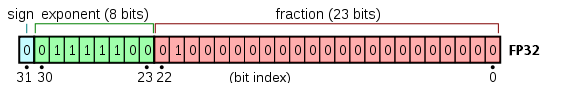

Donde **s** es el valor del signo. **c** es el valor del exponente (con signo).   el valor de la mantissa. 

Los valores de los exponentes con todo 0's o todo 1's, estan reservados. 

### **Denormal number (Single Precision)**

En caso de que el exponente sea 0 y la mantisa sea distinto a 0 entonces representa un "Denormal number". Siguen usando el mismo criterio que los numeros normalizados, es decir, s es el valor del signo y    el valor de la mantissa. El valor del exponente no se utiliza.

### **Double Precision**

la representación en punto flotante con doble precision ocupa 2 words(64 digitos), asignando: 1 bit para el signo del numero real, 11 bits para el exponente y 52 bits para la mantisa.

Un nombre real x en simple precisión se reprensenta de la siguiente manera:

            

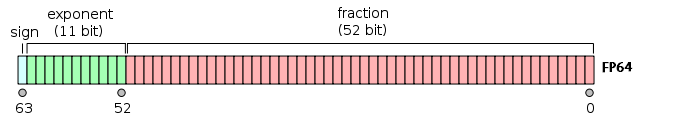

Donde **s** es el valor del del signe. **c** es el valor del exponente (con signo).  el valor de la mantisa.

Los valores de los exponentes con todo 0's o todo 1's, estan reservados. 

### **Denormal number (Double Precision)**

Si el exponente es 0 y la mantisa diferente de 0. 

En caso de que el exponente sea 0 y la mantisa sea distinto a 0 entonces representa un "Denormal number". Siguen usando el mismo criterio que los numeros normalizados, es decir, s es el valor del signo y    el valor de la mantissa. El valor del exponente no se utiliza.

### Inf

Si el exponente es todos 1 y la mantisa es 0 representa a los numeros infinitos. En caso de que el signo sea 0 respresenta el +infinito.En caso de que el signo sea 1 representa -infinito.

### **Nan(Not-A-Number)**

Si el exponente es todos 1 y la mantisa es diferente de 0 representa Nan(Not-A-Number).  Esto se utiliza para expresar un resultado imposible de calcular (raíces negativas, division por cero)...

### **Zero**

Si el exponente es todos 0 y la mantisa 0 representa al 0. En caso de que el signo sea 0 representa el +0. En casi de que el signo sea 1 representa -0.

Fenomenos producidos por la artimetica

# **Fenomenos producidos por la aritmetica **

**roundoff error**

**underflow**

**overflow**

# **Resumen Norma IEEE-754**

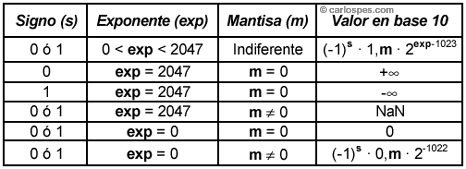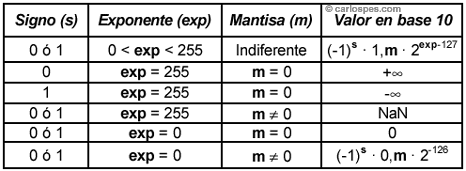

**Biografia:**

[https://es.wikipedia.org/wiki/IEEE_coma_flotante](https://es.wikipedia.org/wiki/IEEE_coma_flotante)

[https://blogs.mathworks.com/cleve/2014/07/07/floating-point-numbers/](https://blogs.mathworks.com/cleve/2014/07/07/floating-point-numbers/)

[https://blogs.mathworks.com/cleve/2014/07/21/floating-point-denormals-insignificant-but-controversial-2/](https://blogs.mathworks.com/cleve/2014/07/21/floating-point-denormals-insignificant-but-controversial-2/)

# Exercici2

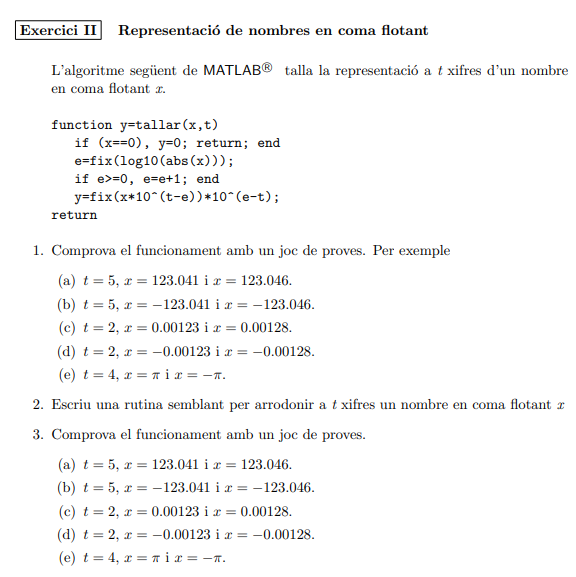

**1. Comprova el funcionament amb un joc de proves. Per exemple:** 

**a)**

format compact
format long
t = 5;
x = 123.051;
ya = tallar(x,t)

ya =      1.230500000000000e+02

x = 123.046;
ya = tallar(x,t)

ya =      1.230400000000000e+02

**b)**

t = 5;
x = -123.051;
yb = tallar(x,t)

yb =     -1.230500000000000e+02

x = -123.046;
yb = tallar(x,t)

yb =     -1.230400000000000e+02

**c)**

t = 2;
x = 0.00123;
yc = tallar(x,t)

yc =    0.001200000000000

x = 0.00123;
yc = tallar(x,t)

yc =    0.001200000000000

**d)**

t = 2;
x = -0.00123;
yd = tallar(x,t)

yd =   -0.001200000000000

x = -0.00123;
yd = tallar(x,t)

yd =   -0.001200000000000

**e)**

t = 4;
x = pi;
ye = tallar(x,t)

ye =    3.141000000000000

x = pi;
ye = tallar(x,t)

ye =    3.141000000000000

**3. Comprova el funcionament amb un joc de proves. Per exemple:** 

**a)**

t = 5;
x = 123.051;
ya = tallar2(x,t)

ya =      1.230510000000000e+02

x = 123.046;
ya = tallar2(x,t)

ya =      1.230460000000000e+02

**b)**

t = 5;
x = -123.051;
yb = tallar2(x,t)

yb =     -1.230510000000000e+02

x = -123.046;
yb = tallar2(x,t)

yb =     -1.230460000000000e+02

**c)**

t = 2;
x = 0.00123;
yc = tallar2(x,t)

yc =    0.001200000000000

x = 0.00123;
yc = tallar2(x,t)

yc =    0.001200000000000

**d)**

t = 2;
x = -0.00123;
yd = tallar2(x,t)

yd =   -0.001200000000000

x = -0.00123;
yd = tallar2(x,t)

yd =   -0.001200000000000

**e)**

t = 4;
x = pi;
ye = tallar2(x,t)

ye =    3.141500000000000

x = pi;
ye = tallar2(x,t)

ye =    3.141500000000000

# Exercici 3

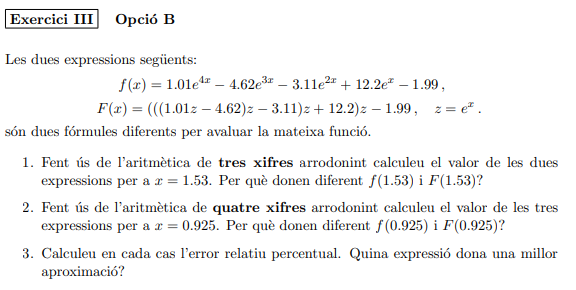

syms x 
syms x 
f = 1.01*e^(4*x)-4.62*e^(3*x)-3.11*e^(x)-1.99

$$f = \frac{101\,{\left(\frac{1}{4503599627370496}\right)}^{4\,x}}{100}-\frac{231\,{\left(\frac{1}{4503599627370496}\right)}^{3\,x}}{50}-\frac{311\,{\left(\frac{1}{4503599627370496}\right)}^{x}}{100}-\frac{199}{100}$$

F = ((((1.01*e^x-4.62)*e^x-3.11)*e^x+12.2)*e^x-1.99)

$$F = {\left(\frac{1}{4503599627370496}\right)}^{x}\,\left({\left(\frac{1}{4503599627370496}\right)}^{x}\,\left({\left(\frac{1}{4503599627370496}\right)}^{x}\,\left(\frac{101\,{\left(\frac{1}{4503599627370496}\right)}^{x}}{100}-\frac{231}{50}\right)-\frac{311}{100}\right)+\frac{61}{5}\right)-\frac{199}{100}$$

sympref('FloatingPointOutput',true);

Error using sympref (line 117)
Expected input to match one of these values:

'FourierParameters', 'HeavisideAtOrigin', 'AbbreviateOutput', 'TypesetOutput'

The input, 'FloatingPointOutput', did not match any of the valid values.

function y=tallar(x,t)
    if x==0
        y = 0;
        return
    end 
    e=fix(log10(abs(x)));
    if e>=0 
        e=e+1;
    end 
    y = fix(x*10^(t-e))*10^(e-t);
    return
end
function y=tallar2(x,t)
    cota_superior = abs(fix(log10(eps)))+1;
    i = 0;
    while (mod(fix(x*10),10) == 0) & i < cota_superior
        x = x * 10;
        i = i + 1;
    end
    y = fix(x*(10^t))*(10^-(t+i));
    return
end